# DOE generation of FEA model

This example shows how to generate a DOE of a FEA LS-Dyna model parameters.

## Import Matlab LS-Dyna (unofficial) library

We here use the matlab LS-Dyna library from Sven Holcombe for pre-post of model and result files. [https://github.com/svenholcombe/matlab-lsdyna](https://github.com/svenholcombe/matlab-lsdyna)

Additional information is provided on the github.

This library enables reading of mesh (reading only), of result files and computation of LSD models.

% Add path to library to Matlab path
folder = fullfile(pwd, '/matlab-lsdyna-master/');
addpath(folder);


## Read LS-Dyna file

The model is based on the thermal stress example on a single element example in [https://www.dynaexamples.com/thermal/thermal-stress.](https://www.dynaexamples.com/thermal/thermal-stress.)

Note, a dummy shell element is needed.

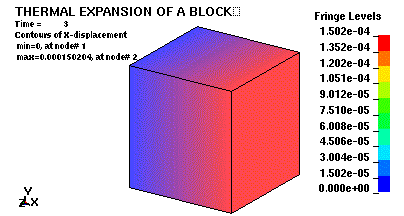

% plot nodes in model
filename = 'thermal-stress.k';
[PART, NODE, ELEMENT_SHELL, ELEMENT_SOLID] = lsdyna.read.kfile(filename);

Reading thermal-stress.k ... read 3K chars in 0.01s.
Splitting contents ... found 85 lines in 0.00s.
Reading keywords ... 18 read in 0.00s
Building keywords list ...  done in 0.00s
Building basic cards ... done in 0.00s
Building specific cards ... done in 0.00s
Parsing lsdyna.keyword.ELEMENT_SHELL cards [1] ... done in 0.06s.
Parsing lsdyna.keyword.ELEMENT_SOLID cards [1] ... done in 0.02s.
Parsing lsdyna.keyword.NODE cards [1] ... done in 0.00s.
Parsing lsdyna.keyword.PART cards [1] ... done in 0.00s.


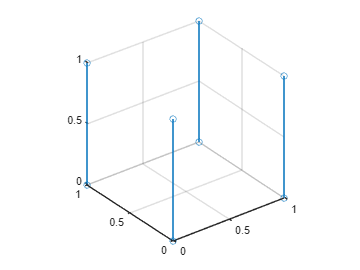

figure, stem3(NODE.x,NODE.y,NODE.z), axis image, view(3)

% figure, plot3(NODE.x,NODE.y,NODE.z), axis image, view(3)

% Read inline
filetext = fileread(filename);

## Create DOE of Applied Temperature

Create Latin Hypercube Sampling (LHS) doe of Applied temperature

rng default % For reproducibility
DOE = lhsdesign(10,1) % between 0 and 1

DOE =     0.7159
    0.2746
    0.4186
    0.6756
    0.8071
    0.9650
    0.5803
    0.0749
    0.1384
    0.3527


## Apply DOE of parameters

Use the LHS DOE to generate a DOE of FEA input files to be computed.

ndoe = 10; % choose even number
temps = zeros(ndoe,1);
newfilenames = strings(ndoe,1);
for index = 1: ndoe

    fprintf('Case %d ------------', index)

    % parameters
    temp = 10 * DOE(index, 1)
    temp = round(temp,3)
    temps(index) = temp

    % open LSD file and change temperature of node 1
    old_text = "         1       10.";
    new_text = sprintf("         1  %8.3f", temp);
    [p,f,e]=fileparts(filename);
    oldfilename=fullfile(p,f);
    newfilename = sprintf('%s_Case_%d.k',oldfilename, index);
    filetext = regexprep(filetext, old_text, new_text);
    filewrite(newfilename, filetext);
    newfilenames(index) = newfilename;
end

Case 1 ------------

temp = 7.1593

temp = 7.1590

temps =     7.1590
         0
         0
         0
         0
         0
         0
         0
         0
         0


newfilenames = 10×1 string array
    "thermal-stress_Case_1.k"
    ""
    ""
    ""
    ""
    ""
    ""
    ""
    ""
    ""


Case 2 ------------

temp = 2.7457

temp = 2.7460

temps =     7.1590
    2.7460
         0
         0
         0
         0
         0
         0
         0
         0


newfilenames = 10×1 string array
    "thermal-stress_Case_1.k"
    "thermal-stress_Case_2.k"
    ""
    ""
    ""
    ""
    ""
    ""
    ""
    ""


Case 3 ------------

temp = 4.1857

temp = 4.1860

temps =     7.1590
    2.7460
    4.1860
         0
         0
         0
         0
         0
         0
         0


newfilenames = 10×1 string array
    "thermal-stress_Case_1.k"
    "thermal-stress_Case_2.k"
    "thermal-stress_Case_3.k"
    ""
    ""
    ""
    ""
    ""
    ""
    ""


Case 4 ------------

temp = 6.7565

temp = 6.7560

temps =     7.1590
    2.7460
    4.1860
    6.7560
         0
         0
         0
         0
         0
         0


newfilenames = 10×1 string array
    "thermal-stress_Case_1.k"
    "thermal-stress_Case_2.k"
    "thermal-stress_Case_3.k"
    "thermal-stress_Case_4.k"
    ""
    ""
    ""
    ""
    ""
    ""


Case 5 ------------

temp = 8.0707

temp = 8.0710

temps =     7.1590
    2.7460
    4.1860
    6.7560
    8.0710
         0
         0
         0
         0
         0


newfilenames = 10×1 string array
    "thermal-stress_Case_1.k"
    "thermal-stress_Case_2.k"
    "thermal-stress_Case_3.k"
    "thermal-stress_Case_4.k"
    "thermal-stress_Case_5.k"
    ""
    ""
    ""
    ""
    ""


Case 6 ------------

temp = 9.6500

temp = 9.6500

temps =     7.1590
    2.7460
    4.1860
    6.7560
    8.0710
    9.6500
         0
         0
         0
         0


newfilenames = 10×1 string array
    "thermal-stress_Case_1.k"
    "thermal-stress_Case_2.k"
    "thermal-stress_Case_3.k"
    "thermal-stress_Case_4.k"
    "thermal-stress_Case_5.k"
    "thermal-stress_Case_6.k"
    ""
    ""
    ""
    ""


Case 7 ------------

temp = 5.8034

temp = 5.8030

temps =     7.1590
    2.7460
    4.1860
    6.7560
    8.0710
    9.6500
    5.8030
         0
         0
         0


newfilenames = 10×1 string array
    "thermal-stress_Case_1.k"
    "thermal-stress_Case_2.k"
    "thermal-stress_Case_3.k"
    "thermal-stress_Case_4.k"
    "thermal-stress_Case_5.k"
    "thermal-stress_Case_6.k"
    "thermal-stress_Case_7.k"
    ""
    ""
    ""


Case 8 ------------

temp = 0.7489

temp = 0.7490

temps =     7.1590
    2.7460
    4.1860
    6.7560
    8.0710
    9.6500
    5.8030
    0.7490
         0
         0


newfilenames = 10×1 string array
    "thermal-stress_Case_1.k"
    "thermal-stress_Case_2.k"
    "thermal-stress_Case_3.k"
    "thermal-stress_Case_4.k"
    "thermal-stress_Case_5.k"
    "thermal-stress_Case_6.k"
    "thermal-stress_Case_7.k"
    "thermal-stress_Case_8.k"
    ""
    ""


Case 9 ------------

temp = 1.3840

temp = 1.3840

temps =     7.1590
    2.7460
    4.1860
    6.7560
    8.0710
    9.6500
    5.8030
    0.7490
    1.3840
         0


newfilenames = 10×1 string array
    "thermal-stress_Case_1.k"
    "thermal-stress_Case_2.k"
    "thermal-stress_Case_3.k"
    "thermal-stress_Case_4.k"
    "thermal-stress_Case_5.k"
    "thermal-stress_Case_6.k"
    "thermal-stress_Case_7.k"
    "thermal-stress_Case_8.k"
    "thermal-stress_Case_9.k"
    ""


Case 10 ------------

temp = 3.5267

temp = 3.5270

temps =     7.1590
    2.7460
    4.1860
    6.7560
    8.0710
    9.6500
    5.8030
    0.7490
    1.3840
    3.5270


newfilenames = 10×1 string array
    "thermal-stress_Case_1.k"
    "thermal-stress_Case_2.k"
    "thermal-stress_Case_3.k"
    "thermal-stress_Case_4.k"
    "thermal-stress_Case_5.k"
    "thermal-stress_Case_6.k"
    "thermal-stress_Case_7.k"
    "thermal-stress_Case_8.k"
    "thermal-stress_Case_9.k"
    "thermal-stress_Case_10.k"


## Compute LS-Dyna models

Compute DOE models. Note, requires FEA solver.

% iterate on generated models
for i = 1:ndoe
  newfilename = newfilenames(index)
  S(i) = lsdyna.simulation(fullfile(newfilename));
end

newfilename = "thermal-stress_Case_10.k"

newfilename = "thermal-stress_Case_10.k"

newfilename = "thermal-stress_Case_10.k"

newfilename = "thermal-stress_Case_10.k"

newfilename = "thermal-stress_Case_10.k"

newfilename = "thermal-stress_Case_10.k"

newfilename = "thermal-stress_Case_10.k"

newfilename = "thermal-stress_Case_10.k"

newfilename = "thermal-stress_Case_10.k"

newfilename = "thermal-stress_Case_10.k"

% requires LS-Dyna model
% S.run % Each simulation will be run, one after the other

Error using isempty
Too many input arguments.

Error in lsdyna.simulation/run (line 126)
            if ~isempty(this.PreSimCallback)

## Takeaways

- FEA connections with current Matlab-LS-DYNA library is limited (only mesh access, no material, bounc access)

- Limitations in mesh reading / visualization in Matlab [https://fr.mathworks.com/matlabcentral/answers/72788-how-can-i-create-a-plot-of-a-3d-mesh-given-node-coordinates-and-element-connectivity-from-an-input-f](https://fr.mathworks.com/matlabcentral/answers/72788-how-can-i-create-a-plot-of-a-3d-mesh-given-node-coordinates-and-element-connectivity-from-an-input-f)

- There is a user plot mesh template in 2D from nodes/connectivities

- Text treatment (startswith, endswith) is complex